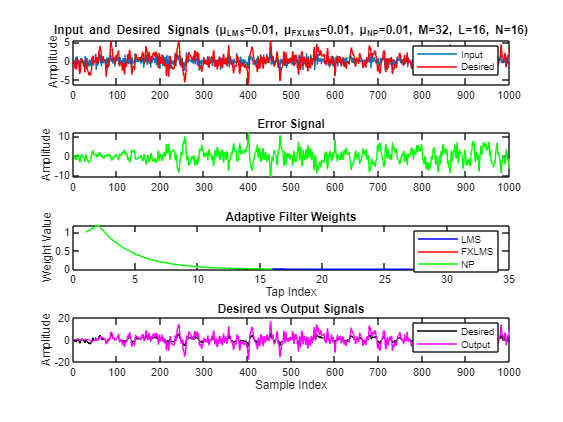

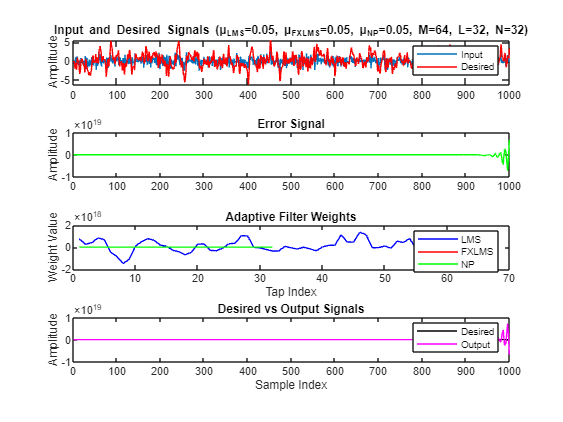

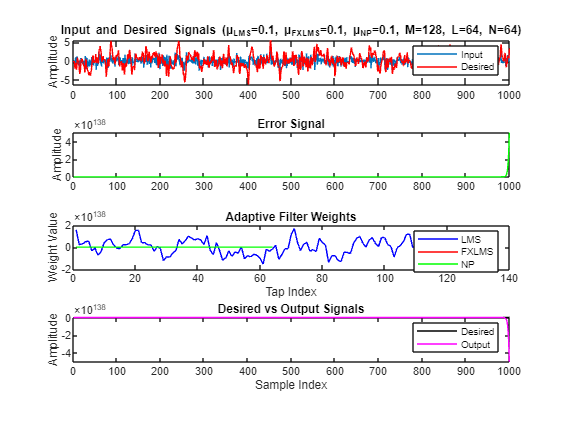

clear all; 
close all; 
clc;

% Parameters for the significant points
significant_points = [
    struct('mu_lms', 0.01, 'mu_fxlms', 0.01, 'mu_np', 0.01, 'M', 32, 'L', 16, 'N', 16),   % Low μ for all, Low M, L, N
    struct('mu_lms', 0.05, 'mu_fxlms', 0.05, 'mu_np', 0.05, 'M', 64, 'L', 32, 'N', 32),   % Medium μ for all, Medium M, L, N
    struct('mu_lms', 0.1, 'mu_fxlms', 0.1, 'mu_np', 0.1, 'M', 128, 'L', 64, 'N', 64)       % High μ for all, High M, L, N
];

% Initialize variables to store results
results = cell(size(significant_points));

% Input signal (noise reference)
x = randn(1000,1);

% Desired signal (noise to be cancelled)
d = filter([1 0.5],[1 -0.7],x);

% Loop over the significant points
for k = 1:numel(significant_points)
    mu_lms = significant_points(k).mu_lms;
    mu_fxlms = significant_points(k).mu_fxlms;
    mu_np = significant_points(k).mu_np;
    M = significant_points(k).M;
    L = significant_points(k).L;
    N = significant_points(k).N;
    
    % Initialize weight vectors
    w_lms = zeros(M,1);     % Filter weights for LMS primary path
    w_ref = zeros(L,1);     % Filter weights for FXLMS reference path
    w_np = zeros(N,1);      % Filter weights for NP path

    % Buffers
    x_buf_lms = zeros(M,1);
    y_buf = zeros(length(d),1);
    x_buf_fxlms = zeros(L,1);
    x_buf_np = zeros(N,1);

    % Main loop
    for n = (max([M,L,N])+1):length(x)

        % LMS
        % Shift input buffer for LMS
        x_buf_lms = x(n:-1:n-M+1); 

        % FIR filter output for LMS primary path
        y_lms = w_lms'*x_buf_lms;

        % Error signal for LMS
        e_lms = d(n) - y_lms;

        % Update weight vector for LMS
        w_lms = w_lms + mu_lms * e_lms * x_buf_lms;

        % FXLMS
        % Shift input buffer for FXLMS reference path
        x_buf_fxlms = x(n:-1:n-L+1);

        % FIR filter output for FXLMS reference path
        y_ref = w_ref'*x_buf_fxlms;

        % Error signal for FXLMS
        e_fxlms = d(n) - y_ref;

        % Update weight vector for FXLMS
        w_ref = w_ref + mu_fxlms * e_fxlms * x_buf_fxlms;

        % NP
        % Shift input buffer for NP path
        x_buf_np = x(n:-1:n-N+1);

        % FIR filter output for NP path
        y_np = w_np'*x_buf_np;

        % Update weight vector for NP
        e_np = d(n) - y_np;
        w_np = w_np + mu_np * e_np * x_buf_np;

        % Final estimate combining LMS, FXLMS, and NP
        y = y_lms + y_ref + y_np;
        y_buf(n) = y;
    end

    % Store results
    results{k} = struct(...
        'mu_lms', mu_lms, ...
        'mu_fxlms', mu_fxlms, ...
        'mu_np', mu_np, ...
        'M', M, ...
        'L', L, ...
        'N', N, ...
        'x', x, ...
        'd', d, ...
        'y_buf', y_buf, ...
        'w_lms', w_lms, ...
        'w_ref', w_ref, ...
        'w_np', w_np ...
    );
end

% Plot signals and weights for each significant point
for k = 1:numel(significant_points)
    figure;
    subplot(4,1,1);
    plot(results{k}.x); hold on; plot(results{k}.d,'r'); legend('Input','Desired');
    ylabel('Amplitude');
    title(['Input and Desired Signals (μ_{LMS}=' num2str(results{k}.mu_lms) ', μ_{FXLMS}=' num2str(results{k}.mu_fxlms) ', μ_{NP}=' num2str(results{k}.mu_np) ', M=' num2str(results{k}.M) ', L=' num2str(results{k}.L) ', N=' num2str(results{k}.N) ')']);

    subplot(4,1,2);
    plot(results{k}.d-results{k}.y_buf,'g'); 
    ylabel('Amplitude');
    title('Error Signal');

    subplot(4,1,3);
    plot(results{k}.w_lms, 'b'); hold on; plot(results{k}.w_ref, 'r'); plot(results{k}.w_np, 'g');
    ylabel('Weight Value');
    xlabel('Tap Index');
    legend('LMS', 'FXLMS', 'NP');
    title('Adaptive Filter Weights');

    subplot(4,1,4);
    plot(results{k}.d, 'k'); hold on; plot(results{k}.y_buf, 'm');
    ylabel('Amplitude');
    xlabel('Sample Index');
    legend('Desired', 'Output');
    title('Desired vs Output Signals');
end

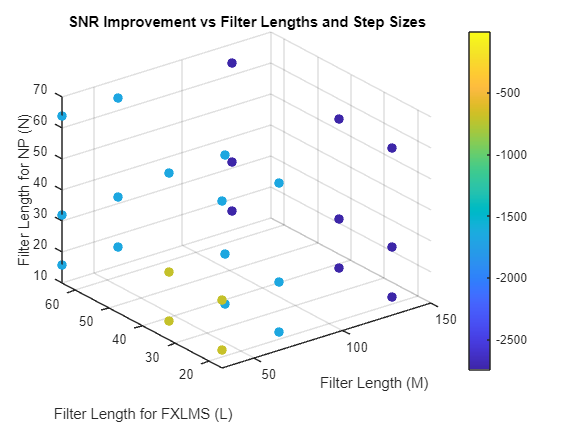


% Parameters for the significant points
significant_M_values = [32, 64, 128];  % Filter length (M)
significant_L_values = [16, 32, 64];   % Filter length for FXLMS (L)
significant_N_values = [16, 32, 64];   % Filter length for NP (N)
significant_mu_lms_values = [0.01, 0.05, 0.1];  % Step size for LMS (μ_{LMS})
significant_mu_fxlms_values = [0.01, 0.05, 0.1];  % Step size for FXLMS (μ_{FXLMS})
significant_mu_np_values = [0.01, 0.05, 0.1];  % Step size for NP (μ_{NP})

% Initialize variables to store results
SNR_improvements = zeros(numel(significant_M_values), numel(significant_L_values), numel(significant_N_values), numel(significant_mu_lms_values), numel(significant_mu_fxlms_values), numel(significant_mu_np_values));
M_values = zeros(numel(significant_M_values), numel(significant_L_values), numel(significant_N_values), numel(significant_mu_lms_values), numel(significant_mu_fxlms_values), numel(significant_mu_np_values));
L_values = zeros(numel(significant_M_values), numel(significant_L_values), numel(significant_N_values), numel(significant_mu_lms_values), numel(significant_mu_fxlms_values), numel(significant_mu_np_values));
N_values = zeros(numel(significant_M_values), numel(significant_L_values), numel(significant_N_values), numel(significant_mu_lms_values), numel(significant_mu_fxlms_values), numel(significant_mu_np_values));
mu_lms_values = zeros(numel(significant_M_values), numel(significant_L_values), numel(significant_N_values), numel(significant_mu_lms_values), numel(significant_mu_fxlms_values), numel(significant_mu_np_values));
mu_fxlms_values = zeros(numel(significant_M_values), numel(significant_L_values), numel(significant_N_values), numel(significant_mu_lms_values), numel(significant_mu_fxlms_values), numel(significant_mu_np_values));
mu_np_values = zeros(numel(significant_M_values), numel(significant_L_values), numel(significant_N_values), numel(significant_mu_lms_values), numel(significant_mu_fxlms_values), numel(significant_mu_np_values));

% Loop over the significant points
for i = 1:numel(significant_M_values)
    M = significant_M_values(i);
    
    for j = 1:numel(significant_L_values)
        L = significant_L_values(j);
        
        for m = 1:numel(significant_N_values)
            N = significant_N_values(m);
            
            for k = 1:numel(significant_mu_lms_values)
                mu_lms = significant_mu_lms_values(k);
                
                for l = 1:numel(significant_mu_fxlms_values)
                    mu_fxlms = significant_mu_fxlms_values(l);
                    
                    for n = 1:numel(significant_mu_np_values)
                        mu_np = significant_mu_np_values(n);
                        
                        % Initialize weight vectors
                        w_lms = zeros(M,1);     % Filter weights for LMS primary path
                        w_ref = zeros(L,1);     % Filter weights for FXLMS reference path
                        w_np = zeros(N,1);      % Filter weights for NP path

                        % Buffers
                        x_buf_lms = zeros(M,1);
                        y_buf = zeros(length(d),1);
                        x_buf_fxlms = zeros(L,1);
                        x_buf_np = zeros(N,1);

                        % Main loop
                        for o = (max([M,L,N])+1):length(x)

                            % LMS
                            % Shift input buffer for LMS
                            x_buf_lms = x(o:-1:o-M+1); 

                            % FIR filter output for LMS primary path
                            y_lms = w_lms'*x_buf_lms;

                            % Error signal for LMS
                            e_lms = d(o) - y_lms;

                            % Update weight vector for LMS
                            w_lms = w_lms + mu_lms * e_lms * x_buf_lms;

                            % FXLMS
                            % Shift input buffer for FXLMS reference path
                            x_buf_fxlms = x(o:-1:o-L+1);

                            % FIR filter output for FXLMS reference path
                            y_ref = w_ref'*x_buf_fxlms;

                            % Error signal for FXLMS
                            e_fxlms = d(o) - y_ref;

                            % Update weight vector for FXLMS
                            w_ref = w_ref + mu_fxlms * e_fxlms * x_buf_fxlms;

                            % NP
                            % Shift input buffer for NP path
                            x_buf_np = x(o:-1:o-N+1);

                            % FIR filter output for NP path
                            y_np = w_np'*x_buf_np;

                            % Update weight vector for NP
                            e_np = d(o) - y_np;
                            w_np = w_np + mu_np * e_np * x_buf_np;

                            % Final estimate combining LMS, FXLMS, and NP
                            y = y_lms + y_ref + y_np;
                            y_buf(o) = y;
                        end

                        % Calculate Signal-to-Noise Ratio (SNR)
                        SNR_input = snr(d, d - x); % SNR of input signal
                        SNR_output = snr(d, d - y_buf); % SNR of output signal

                        % Store SNR improvement
                        SNR_improvements(i, j, m, k, l, n) = SNR_output - SNR_input;
                        M_values(i, j, m, k, l, n) = M;
                        L_values(i, j, m, k, l, n) = L;
                        N_values(i, j, m, k, l, n) = N;
                        mu_lms_values(i, j, m, k, l, n) = mu_lms;
                        mu_fxlms_values(i, j, m, k, l, n) = mu_fxlms;
                        mu_np_values(i, j, m, k, l, n) = mu_np;
                    end
                end
            end
        end
    end
end

% Convert matrices to vectors for plotting
SNR_improvements_vector = SNR_improvements(:);
M_values_vector = M_values(:);
L_values_vector = L_values(:);
N_values_vector = N_values(:);
mu_lms_values_vector = mu_lms_values(:);
mu_fxlms_values_vector = mu_fxlms_values(:);
mu_np_values_vector = mu_np_values(:);

% Create 3D scatter plot
figure;
scatter3(M_values_vector, L_values_vector, N_values_vector, 50, SNR_improvements_vector, 'filled');
xlabel('Filter Length (M)');
ylabel('Filter Length for FXLMS (L)');
zlabel('Filter Length for NP (N)');
colorbar;
title('SNR Improvement vs Filter Lengths and Step Sizes');


% Plot the best combination
[max_SNR, idx] = max(SNR_improvements_vector);
best_M = M_values_vector(idx);
best_L = L_values_vector(idx);
best_N = N_values_vector(idx);
best_mu_lms = mu_lms_values_vector(idx);
best_mu_fxlms = mu_fxlms_values_vector(idx);
best_mu_np = mu_np_values_vector(idx);

disp(['Best combination - Step size for LMS (μ_lms): ' num2str(best_mu_lms) ', Step size for FXLMS (μ_fxlms): ' num2str(best_mu_fxlms) ', Step size for NP (μ_np): ' num2str(best_mu_np) ', Filter order (M): ' num2str(best_M) ', Filter length for FXLMS (L): ' num2str(best_L) ', Filter length for NP (N): ' num2str(best_N)]);

Best combination - Step size for LMS (μ_lms): 0.01, Step size for FXLMS (μ_fxlms): 0.01, Step size for NP (μ_np): 0.01, Filter order (M): 128, Filter length for FXLMS (L): 16, Filter length for NP (N): 16
